# Analisis espacio-temporal de la region hidrografica #26 Río Pánuco

import matlab.io.hdfeos.*
clearvars -except study_area;

%directorio de datos
dir_data = "D:\DATA\";
modis_product = 'MOD13A2';
kml_file = "RH26";

m_cargar_datos

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1078 archivos
>>>>> Obteniendo la zona de estudio
D:\DATA\MOD13A2\061\*.hdf
>>>>> Analizando 1078 archivos
>>>>> Obteniendo latitud y longitud
>>> Cargando área de estudio
>>> Área de estudio existente 1


#### Mostrar el promedio de NDVI Media Juliana de toda la serie

ndvi_prom = m_mean_3dpp(arr_ndvi_mj);
ndvi_prom(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,kml_file,1,'k');

promedio = mean(ndvi_prom,"all","omitnan");
disp("Promedio: "+promedio);

Promedio: 0.54784


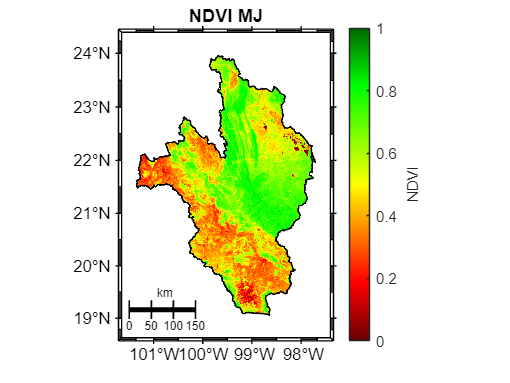


exportgraphics(gca,"img/aet_promedio_ndvi_mj.png",'Resolution',300);